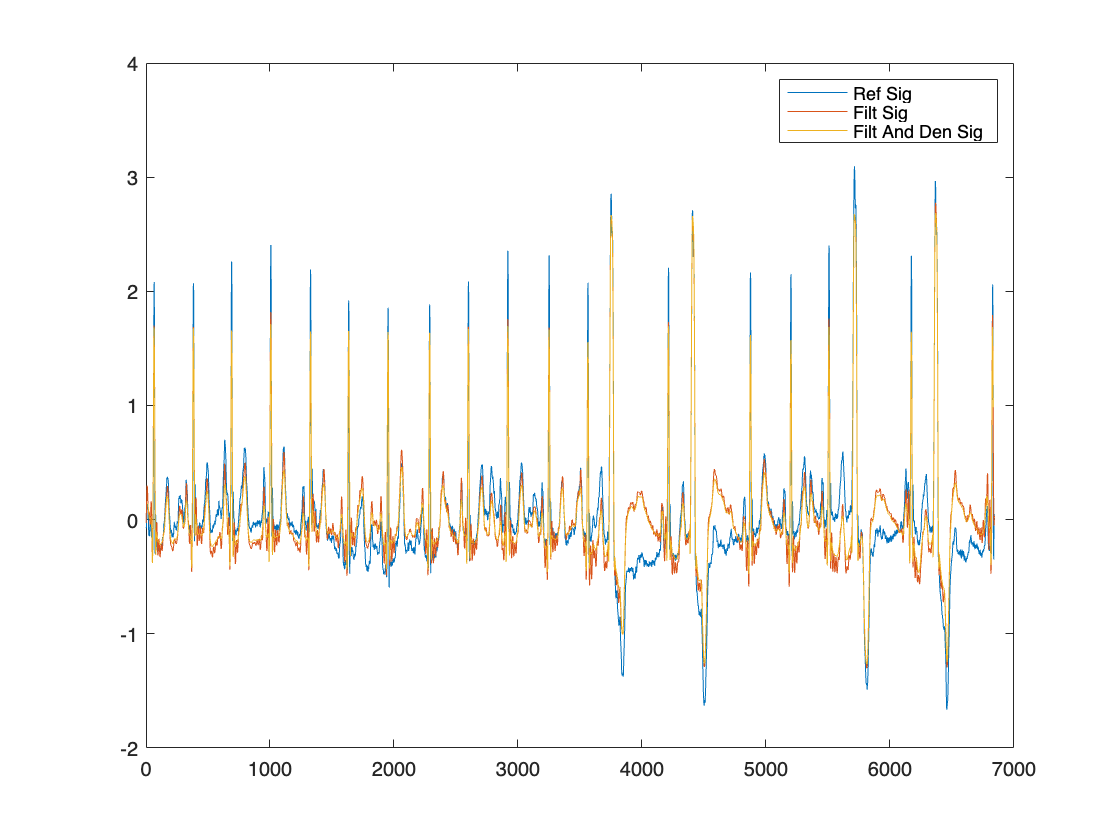

err =     0.2371         0         0         0         0         0


psnr_den =     6.2504         0         0         0         0         0


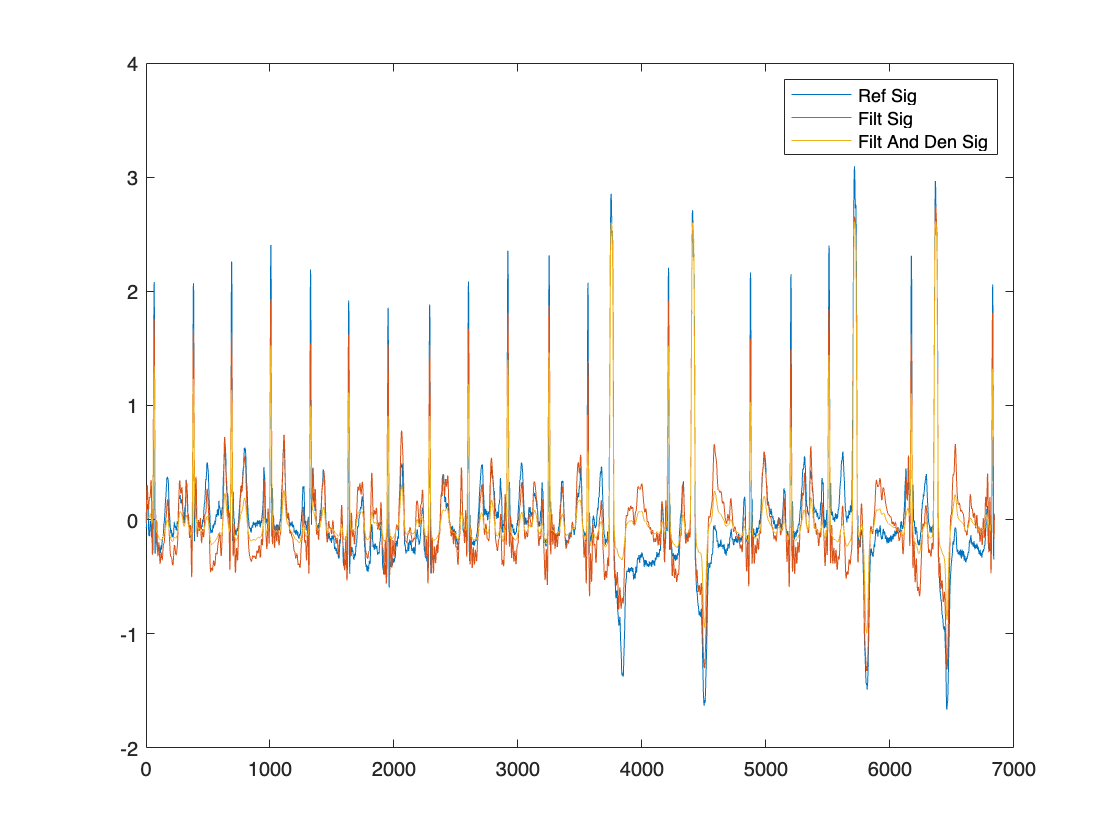

err =     0.2371    0.2305         0         0         0         0


psnr_den =     6.2504    6.3733         0         0         0         0


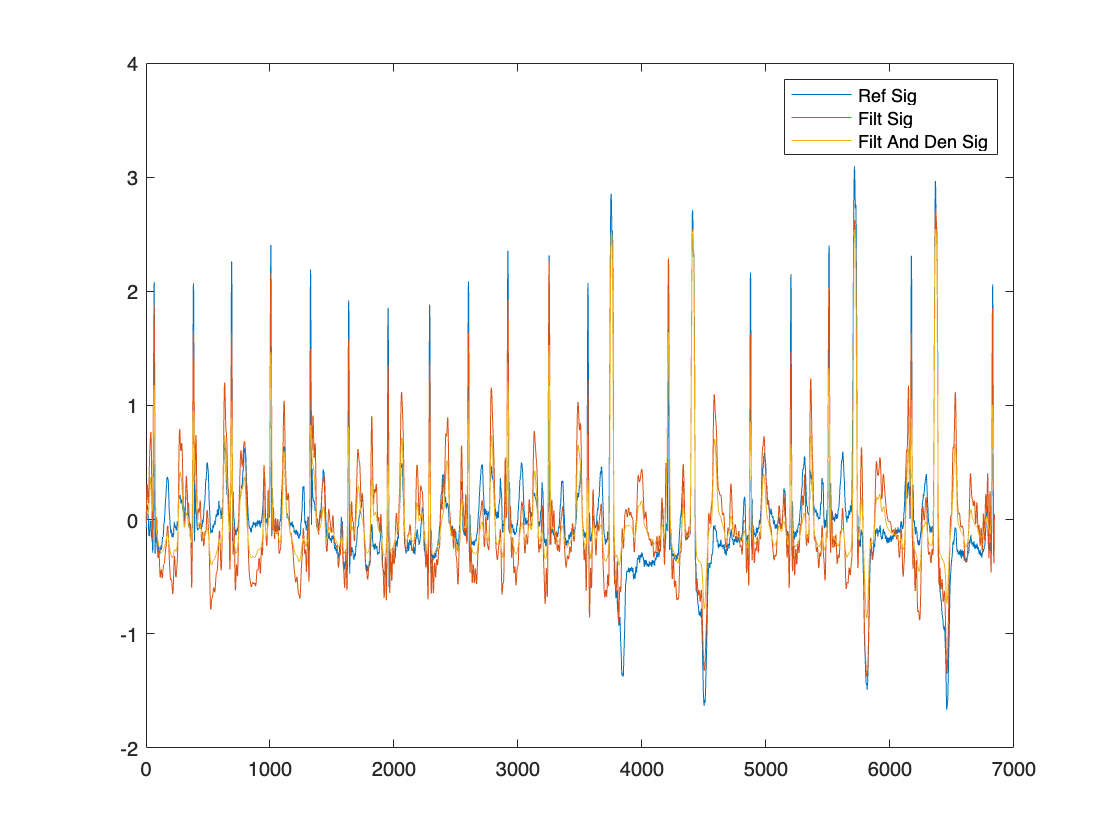

err =     0.2371    0.2305    0.2344         0         0         0


psnr_den =     6.2504    6.3733    6.3007         0         0         0


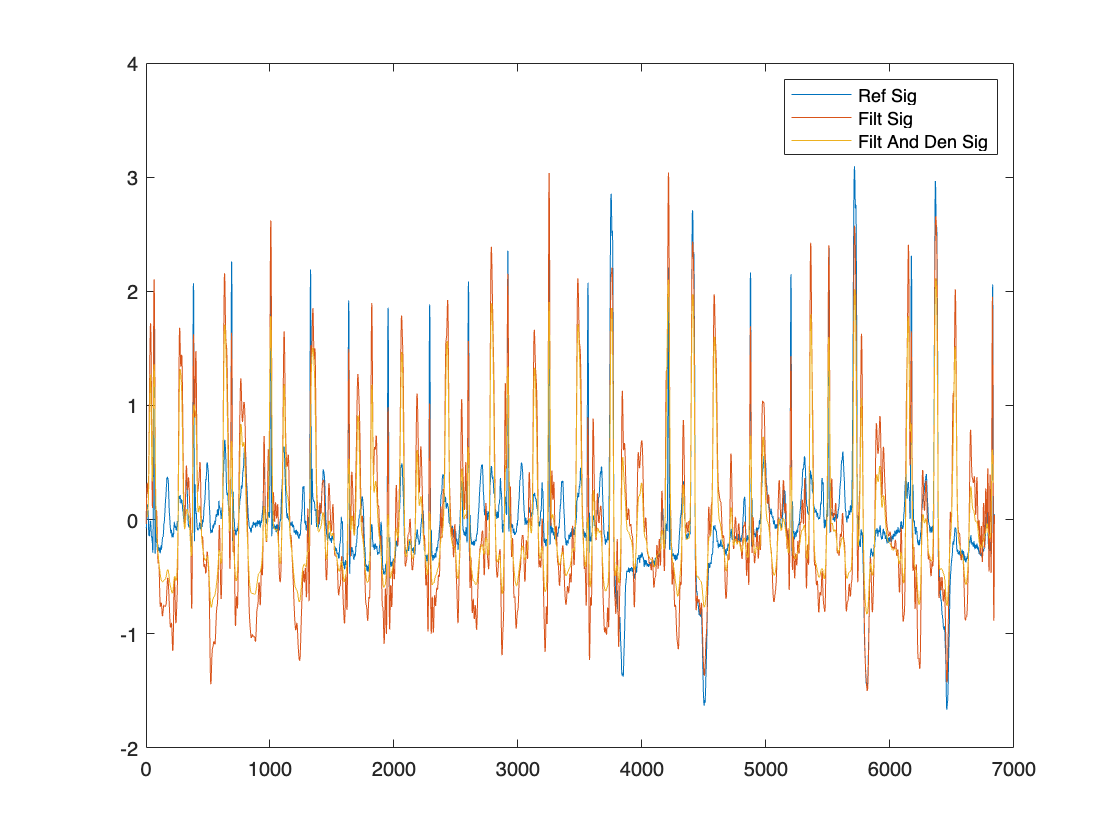

err =     0.2371    0.2305    0.2344    0.3750         0         0


psnr_den =     6.2504    6.3733    6.3007    4.2601         0         0


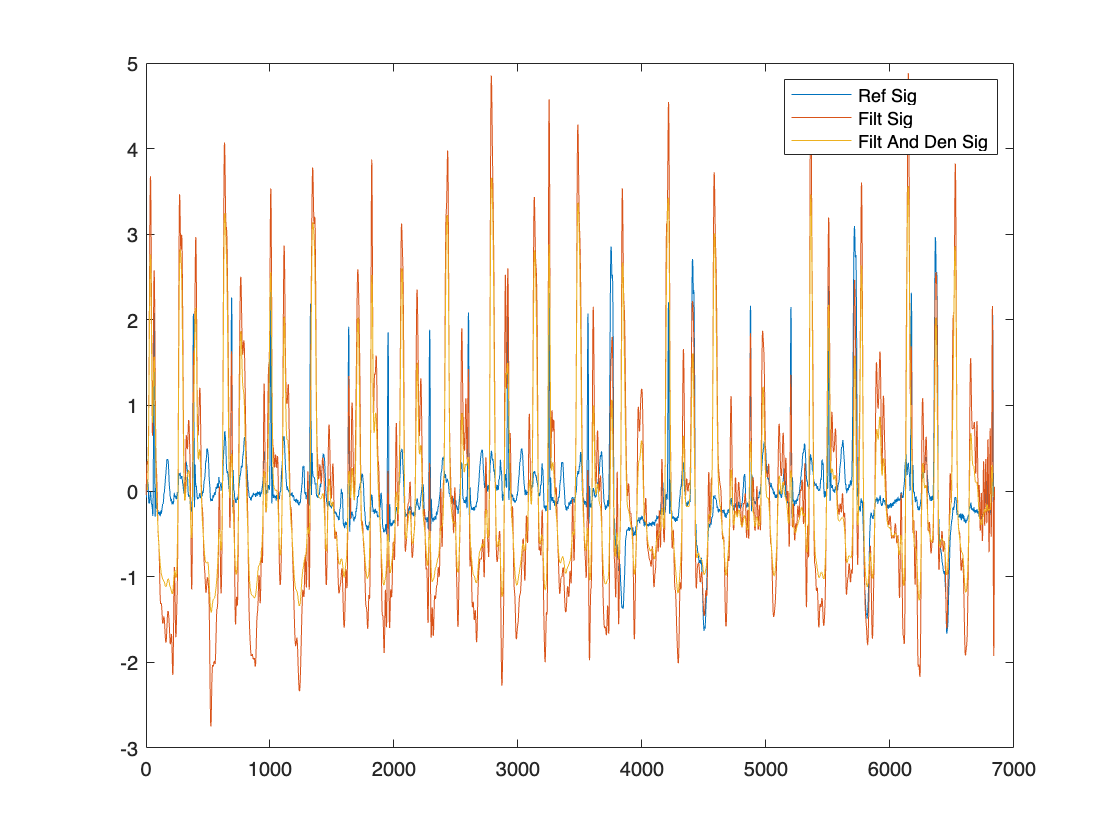

err =     0.2371    0.2305    0.2344    0.3750    1.0299         0


psnr_den =     6.2504    6.3733    6.3007    4.2601   -0.1279         0


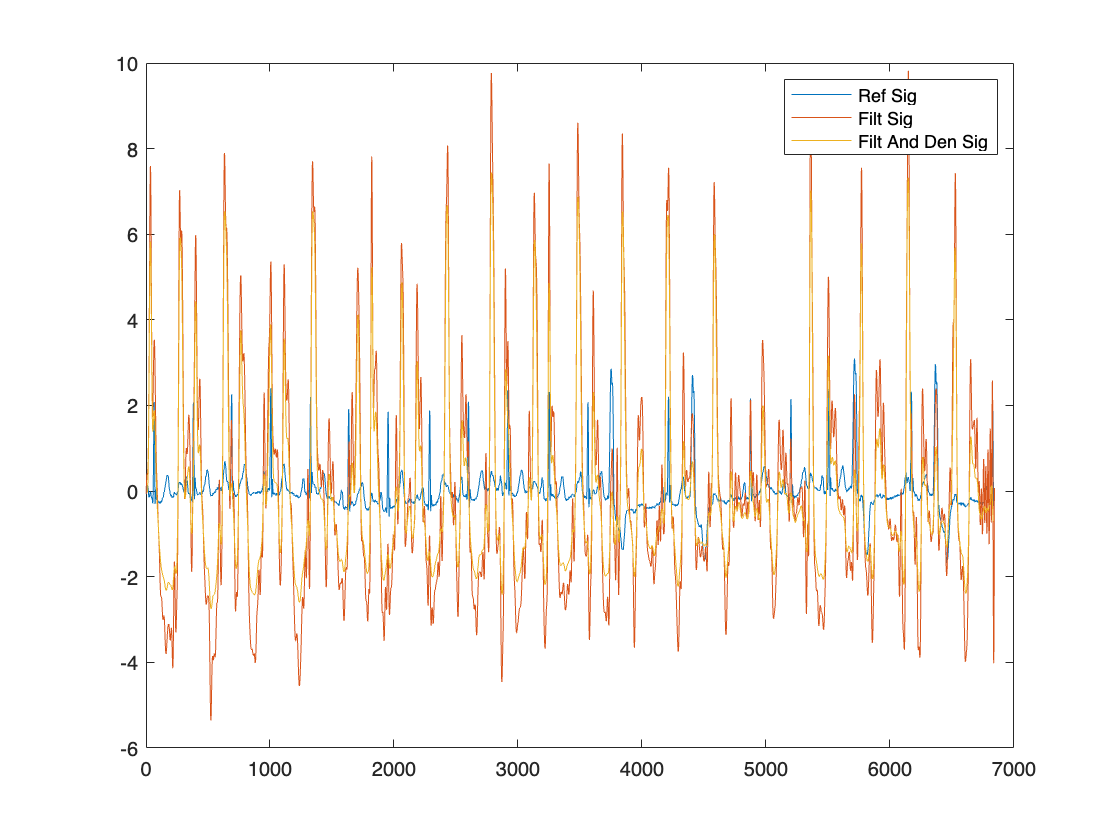

err =     0.2371    0.2305    0.2344    0.3750    1.0299    3.7406


psnr_den =     6.2504    6.3733    6.3007    4.2601   -0.1279   -5.7295



load nstdb_dataset.mat
%i = 12; 
iref = 7; 
Fs = 360; 
psnr_den = zeros(1,6);
err = zeros(1,6);
for i = 7:12
    reference_sig = ecg{iref,1}(350*Fs:370*Fs) - mean(ecg{iref,1}(350*Fs:370*Fs));
    sig = ecg{i,1}(350*Fs:370*Fs) - mean(ecg{i,1}(350*Fs:370*Fs));
    sig = bandpass(sig, [1, 20], Fs); % Replace Fs with your sampling frequency
    sig = sig(1*Fs:end);
    reference_sig = reference_sig(1*Fs:end);
    PatchHW=10;  % patch half-width; ~ size of smallest feature, in samples
    P = 7000;    % neighborhood search width; wider=more computation but more
                 % channces to find a similar patch
    
    % set bandwidth for NLM - here set by an "eyeball estimate" 
    lambda = 0.6*std(sig);
    [denoisedSig,debug] = NLM_1dDarbon(sig,lambda,P,PatchHW);
    figure;
    plot(reference_sig);
    hold on; 
    plot(sig);
    hold on; 
    plot(denoisedSig);
    legend("Ref Sig","Filt Sig","Filt And Den Sig")
    nanvals = ~isnan(denoisedSig);
    denoisedSig = denoisedSig(~isnan(denoisedSig));
    reference_sig = reference_sig(~isnan(denoisedSig));
    err(i-6) = immse(reference_sig,denoisedSig)
    psnr_den(i-6) = psnr(reference_sig,denoisedSig)
end 

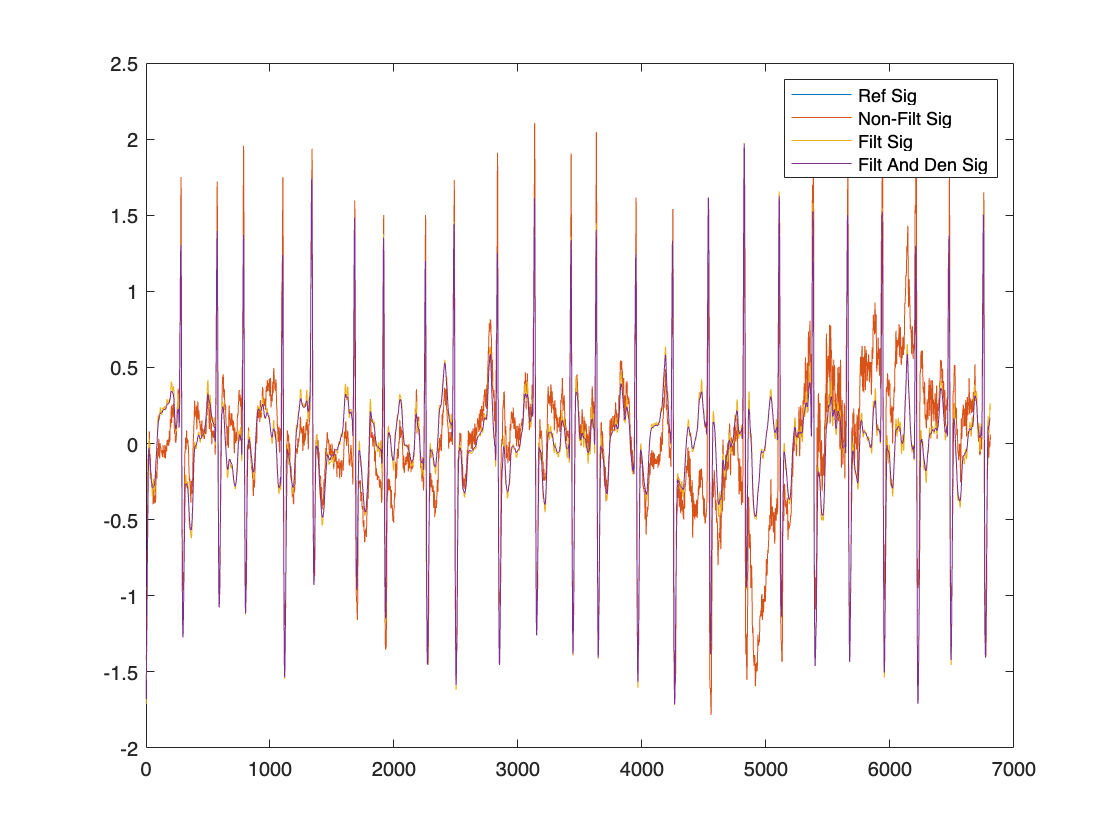

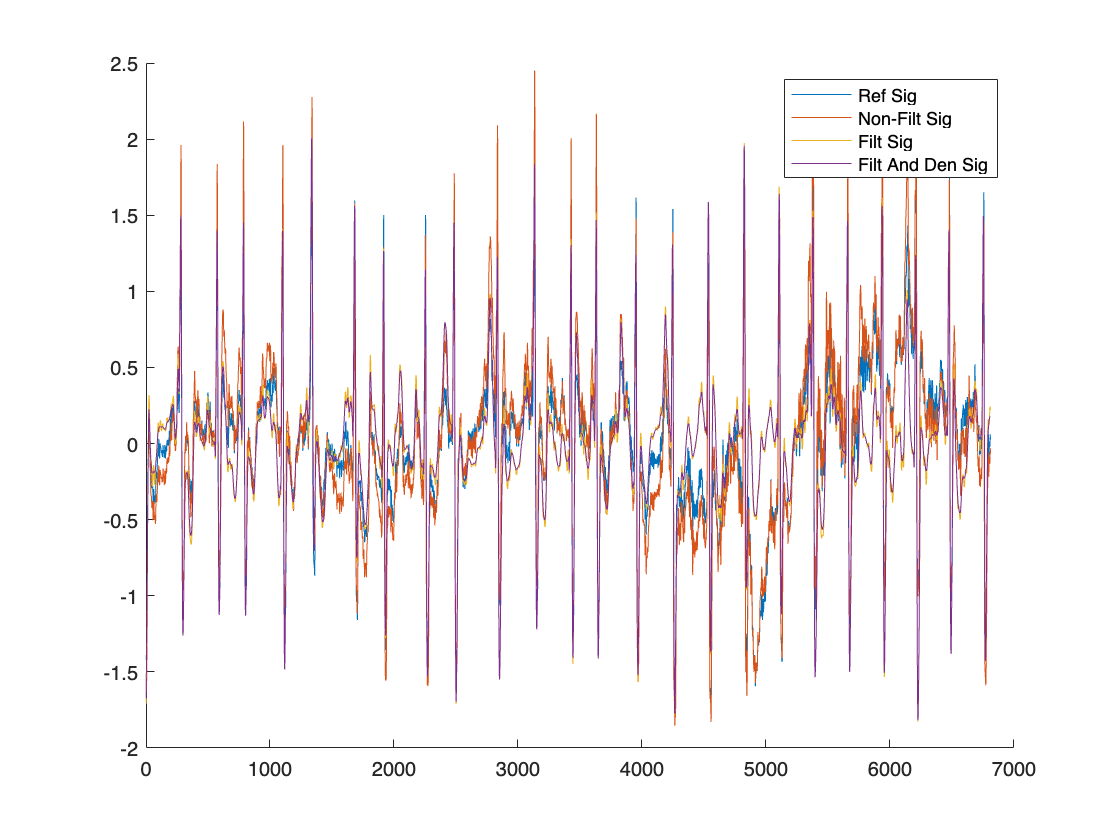

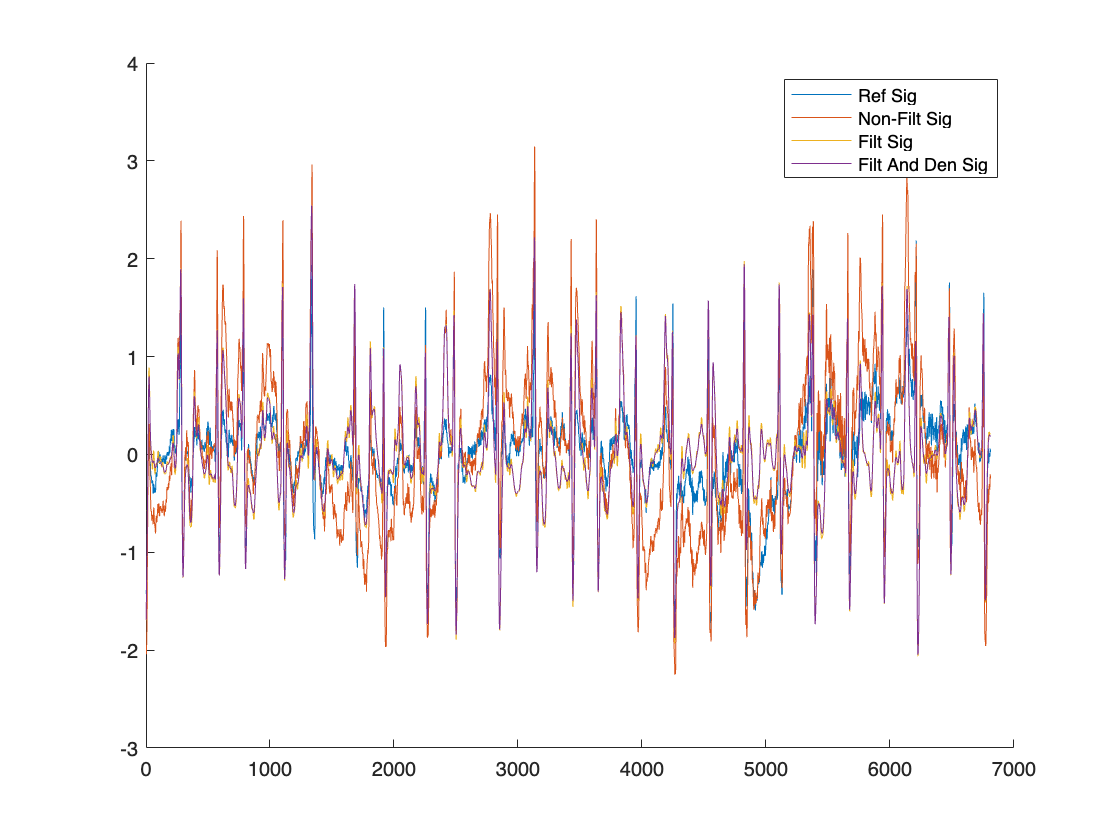

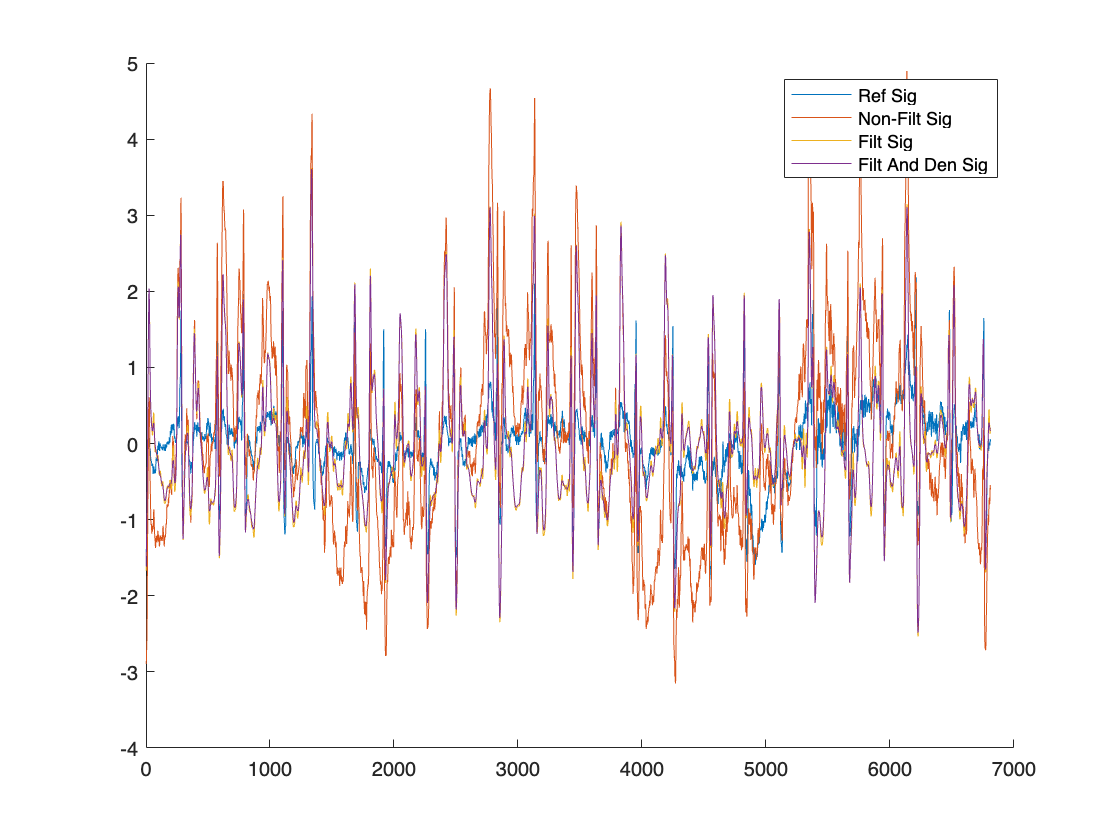

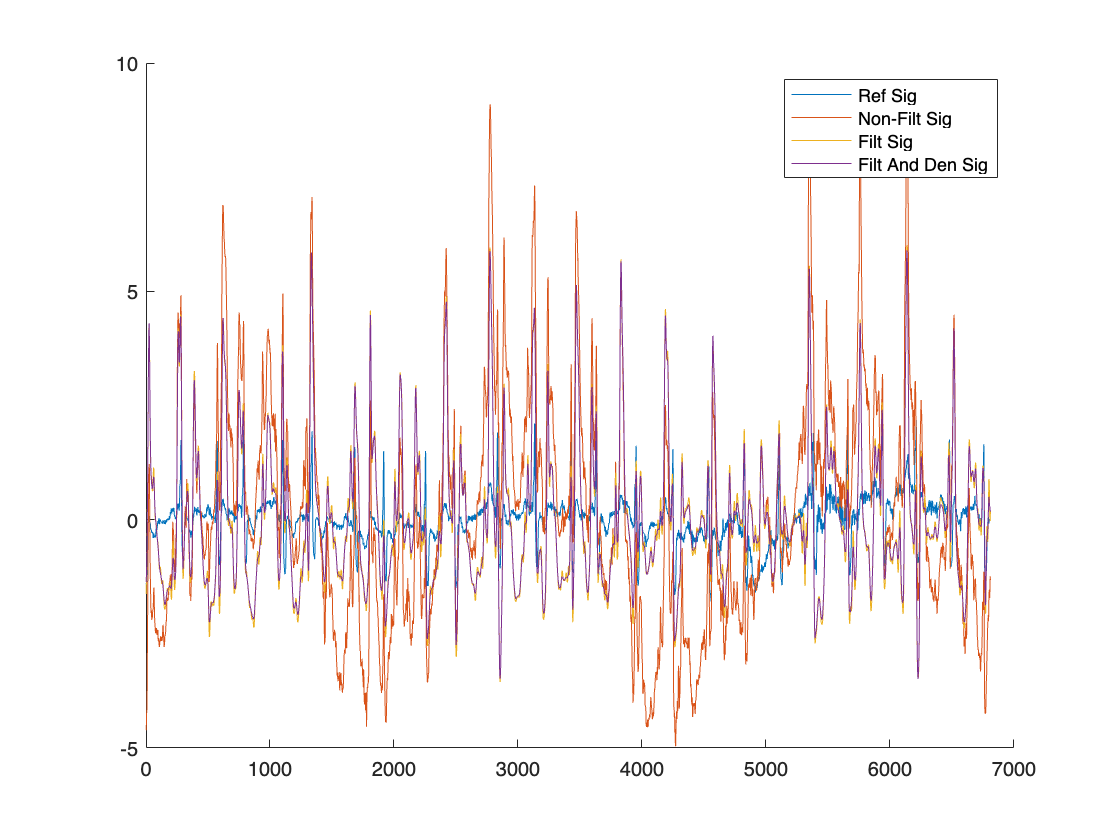

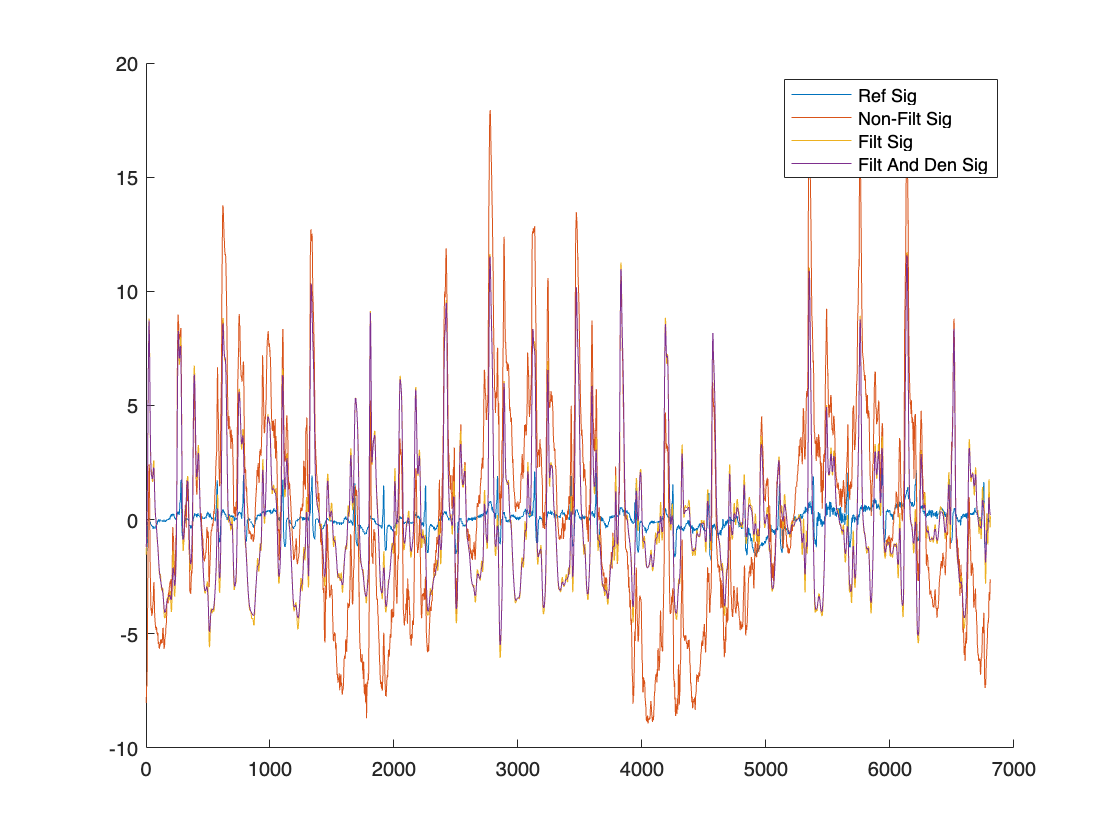

load nstdb_dataset.mat
iref = 1; 
Fs = 360; 
psnr_den = zeros(1,6);
mse_den = zeros(1,6);
psnr_filt = zeros(1,6);
mse_filt = zeros(1,6);
for i = 1:6
    reference_sig = ecg{iref,1}(350*Fs:370*Fs) - mean(ecg{iref,1}(350*Fs:370*Fs));
    orig_sig = ecg{i,1}(350*Fs:370*Fs) - mean(ecg{i,1}(350*Fs:370*Fs));
    sig = bandpass(orig_sig, [1, 20], Fs); % Replace Fs with your sampling frequency
    sig = sig(1*Fs:end);
    reference_sig = reference_sig(1*Fs:end);
    orig_sig = orig_sig(1*Fs:end);
    PatchHW=10;  % patch half-width; ~ size of smallest feature, in samples
    P = 5000;    % neighborhood search width; wider=more computation but more
                 % channces to find a similar patch
    
    % set bandwidth for NLM - here set by an "eyeball estimate" 
    lambda = 0.6*std(sig)/5;
    [denoisedSig,debug] = NLM_1dDarbon(sig,lambda,P,PatchHW);
    nanvals = ~isnan(denoisedSig);
    denoisedSig = (denoisedSig(~isnan(denoisedSig)));
    reference_sig = (reference_sig(~isnan(denoisedSig)));
    sig = (sig(~isnan(denoisedSig)));
    orig_sig = (orig_sig(~isnan(denoisedSig)));
    figure; hold on; 
    plot(reference_sig(12:end));
    plot(orig_sig(12:end));
    plot(sig(12:end));
    plot(denoisedSig(1:end-11));
    legend("Ref Sig","Non-Filt Sig","Filt Sig","Filt And Den Sig")

    mse_den(i) = immse(denoisedSig(1:end-11),reference_sig(12:end));
    psnr_den(i) = psnr(denoisedSig(1:end-11),reference_sig(12:end));
    mse_filt(i) = immse(sig,reference_sig);
    psnr_filt(i) = psnr(sig,reference_sig);
end


mse_filt

mse_filt =     0.0973    0.1016    0.1624    0.4923    1.9816    8.2616


mse_den

mse_den =     0.0969    0.0998    0.1565    0.4721    1.9087    7.9514


psnr_filt

psnr_filt =    10.1186    9.9298    7.8929    3.0779   -2.9701   -9.1706


psnr_den

psnr_den =    10.1360   10.0068    8.0561    3.2599   -2.8074   -9.0044
